%% Initializations
clc; clear; close all;

g = 9.81;   % The gravitational acceleration [m/s^2]
l =  0.2;   % Distance from the center of mass to each rotor [m]
m =  0.5;   % Total mass of the quadrotor [kg]
I = [1.24, 1.24, 2.48]; % Mass moment of inertia [kg m^2]
mu = 3.0;   % Maximum thrust of each rotor [N]
sigma = 0.01; % The proportionality constant relating thrust to torque [m]

hover_mu = (m*g)/4;
e_max = l/2;

p = [g l m I mu sigma];

invadeInit = [2;0;2];

% Initial conditions
% z0 = zeros(12,1);
z0 = [0; 0; 0; 0; 0; 0; 0; 0; 0; 0; 0; 0; invadeInit];

r = [0; 0; 0];
n = [0; 0; 0];
%u = [1; 1.1; 1.9; 1.2]; % Original "u"
u = [1; 1; 1; 1]; % u1 across from u3 (CCW), u2 across from u4 (CW)

% Desired Point
xd = [-1; 0; 1];

%% Solving the initial-value problem

t = linspace(0, 10, 300);

fis_height = readfis('fuzzy_height');
fis_pitch = readfis('fuzzy_theta');
fis_roll = readfis('fuzzy_phi');

% Invader Copter
invadeCopter = @(t,b) [-1/2,1.5*cos(t),0];

[t,z] = ode45(@(t,z) quadrotor(t, z, u, p, r, n, xd, fis_height, fis_pitch, fis_roll, invadeCopter, e_max), t, z0);

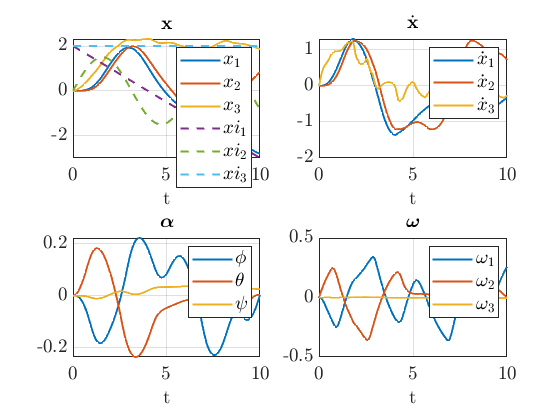



%% Plotting the results

for i=1:4
    ax(i) = subplot(2,2,i,'NextPlot','Add','Box','on','XGrid','on','YGrid','on',...
                'Xlim',[t(1), t(end)],...
                'TickLabelInterpreter','LaTeX','FontSize',14);
    xlabel('t','Interpreter','LaTeX','FontSize',14);        
end


plot(ax(1), t,z(:,1:3), 'LineWidth', 1.5);
plot(ax(1), t,z(:,13:15),'--','LineWidth', 1.5);
legend(ax(1), {'$x_1$', '$x_2$', '$x_3$','$xi_1$', '$xi_2$', '$xi_3$'},... 
    'Interpreter', 'LaTeX', 'FontSize', 14);
title(ax(1), '${\bf x}$','Interpreter','LaTeX','FontSize',14);
xlabel(ax(1), 't','Interpreter','LaTeX','FontSize',14);

plot(ax(3), t, z(:,4:6), 'LineWidth', 1.5);
legend(ax(3), {'$\phi$', '$\theta$', '$\psi$'},...
    'Interpreter', 'LaTeX', 'FontSize', 14);
title(ax(3), '\boldmath$\alpha$','Interpreter','LaTeX','FontSize',14);

plot(ax(2), t, z(:,7:9), 'LineWidth', 1.5);
legend(ax(2), {'$\dot{x}_1$', '$\dot{x}_2$', '$\dot{x}_3$'},...
    'Interpreter', 'LaTeX', 'FontSize', 14);
title(ax(2), '$\dot{\bf x}$','Interpreter','LaTeX','FontSize',14);

plot(ax(4), t, z(:,10:12), 'LineWidth', 1.5);
legend(ax(4), {'$\omega_1$', '$\omega_2$', '$\omega_3$'},...
    'Interpreter', 'LaTeX', 'FontSize', 14);
title(ax(4), '\boldmath$\omega$','Interpreter','LaTeX','FontSize',14);

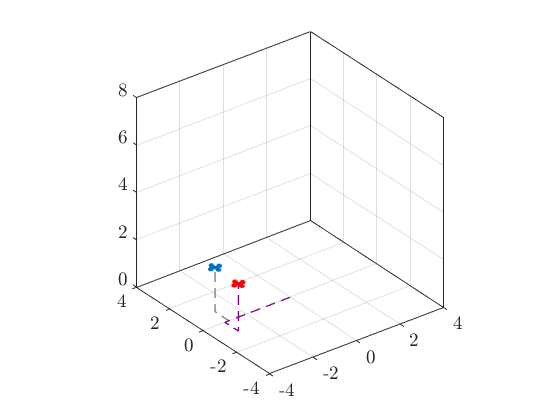




%% Animation
animation_fig = figure;

airspace_box_length = 8;

animation_axes = axes('Parent', animation_fig,...
    'NextPlot','add','DataAspectRatio',[1 1 1],...
    'Xlim',airspace_box_length*[-0.5 0.5],...
    'Ylim',airspace_box_length*[-0.5 0.5],...
    'Zlim',airspace_box_length*[0 1],...
    'box','on','Xgrid','on','Ygrid','on','Zgrid','on',...
    'TickLabelInterpreter','LaTeX','FontSize',14);

view(animation_axes, 3);

N = 10;
Q = linspace(0,2*pi,N)';
circle = 0.3*l*[cos(Q) sin(Q) zeros(N,1)];
loc = l*[1 0 0; 0 1 0; -1 0 0; 0 -1 0];


silhouette = plot3(0,0,0, '--', 'Color', 0.5*[1 1 1], 'LineWidth', 1 ,...
    'Parent', animation_axes);
body = plot3(0,0,0, 'Color',lines(1), 'LineWidth', 2,...
        'Parent', animation_axes);
for i=1:4
    rotor(i) = plot3(0,0,0, 'Color', lines(1), 'LineWidth', 2,...
        'Parent', animation_axes);
end

silhouette2 = plot3(0,0,0, '--', 'Color', 0.5*[1 0 1], 'LineWidth', 1 ,...
    'Parent', animation_axes);
body2 = plot3(0,0,0, 'Color',[1 0 0], 'LineWidth', 2,...
        'Parent', animation_axes);
for i=1:4
    rotor2(i) = plot3(0,0,0, 'Color', [1 0 0], 'LineWidth', 2,...
        'Parent', animation_axes);
end

tic;
for k=1:length(t)
    
    R = [ cos(z(k,5))*cos(z(k,6)), sin(z(k,4))*sin(z(k,5))*cos(z(k,6)) - cos(z(k,4))*sin(z(k,6)), sin(z(k,4))*sin(z(k,6)) + cos(z(k,4))*sin(z(k,5))*cos(z(k,6));
          cos(z(k,5))*sin(z(k,6)), cos(z(k,4))*cos(z(k,6)) + sin(z(k,4))*sin(z(k,5))*sin(z(k,6)), cos(z(k,4))*sin(z(k,5))*sin(z(k,6)) - sin(z(k,4))*cos(z(k,6));
                     -sin(z(k,5)),                                 sin(z(k,4))*cos(z(k,5)),                                 cos(z(k,4))*cos(z(k,5))];
    for i=1:4
        ctr(i,:) = z(k,1:3) + loc(i,:)*R';
        pose = ones(N,1)*z(k,1:3) + (ones(N,1)*loc(i,:) + circle)*R';
        set(rotor(i), 'XData', pose(:,1), 'YData', pose(:,2),  'ZData', pose(:,3) );
        
        ctr2(i,:) = z(k,13:15) + loc(i,:)*R';
        pose2 = ones(N,1)*z(k,13:15) + (ones(N,1)*loc(i,:) + circle)*R';
        set(rotor2(i), 'XData', pose2(:,1), 'YData', pose2(:,2),  'ZData', pose2(:,3) );
         
    end
    set(silhouette,'XData', [0, z(k,1), z(k,1), z(k,1)],...
        'YData', [0, 0, z(k,2), z(k,2)],...
        'ZData', [0, 0, 0, z(k,3)]);
    set(body, 'XData', [ctr([1 3],1); NaN; ctr([2 4],1)], ...
        'YData', [ctr([1 3],2); NaN; ctr([2 4],2)],...
        'ZData', [ctr([1 3],3); NaN; ctr([2 4],3)] );
    
    set(silhouette2,'XData', [0, z(k,13), z(k,13), z(k,13)],...
        'YData', [0, 0, z(k,14), z(k,14)],...
        'ZData', [0, 0, 0, z(k,15)]);
    set(body2, 'XData', [ctr2([1 3],1); NaN; ctr2([2 4],1)], ...
        'YData', [ctr2([1 3],2); NaN; ctr2([2 4],2)],...
        'ZData', [ctr2([1 3],3); NaN; ctr2([2 4],3)] );
    
    pause(t(k)-toc);
    pause(0.01);
end

function dz = quadrotor(t, z, u, p, r, n, xd, hctrl, xctrl,yctrl, goal, e_cap) 
% State vector definition
%
%      x1, x2, x3, phi, theta, psi, dx1, dx2, dx3, omega1, omega2, omega3
% z = [z1, z2, z3,  z4,    z5,  z6,  z7,  z8,  z9,    z10,    z11,    z12]
%
% Parameter vector definition
%
%       g,  l,  m, I11, I22, I33, mu, sigma
% p = [p1, p2, p3,  p4,  p5,  p6, p7,    p8]


% Forming the moment of inertia tensor based on the parametr values
I = diag(p(4:6)); 


% Rotation matrix mapping body fixed frame C to inertial frame E
R = [ cos(z(5))*cos(z(6)), sin(z(4))*sin(z(5))*cos(z(6)) - cos(z(4))*sin(z(6)), sin(z(4))*sin(z(6)) + cos(z(4))*sin(z(5))*cos(z(6));
      cos(z(5))*sin(z(6)), cos(z(4))*cos(z(6)) + sin(z(4))*sin(z(5))*sin(z(6)), cos(z(4))*sin(z(5))*sin(z(6)) - sin(z(4))*cos(z(6));
               -sin(z(5)),                                 sin(z(4))*cos(z(5)),                                 cos(z(4))*cos(z(5))];

           


%%%%%%%%%%%%%%%%%%%%%%%%% ADDED CONTENT %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Dampeners
D = 1*diag([1,1,1]);

T = 1*diag([1,1,1]);

% Rotation Matrix in regards to the Z axis
rot_z = [cos(z(6)) -sin(z(6)) 0;
         sin(z(6)) cos(z(6)) 0;
         0 0 1];

% Invader Copter Position
b = z(13:15);

% First the Error...
% TODO: divisor needs to be changed to reflect the euclidean distance
%       between starting and ending points

% err = (rot_z*xd -[z(1); z(2); z(3)])./abs(xd);
% err = (rot_z*xd -[z(1); z(2); z(3)]);

% err = (rot_z*b -[z(1); z(2); z(3)])./abs(b);
err = (rot_z*b -[z(1); z(2); z(3)]);


% Current Velocity
v = [z(7); z(8); z(9)];

% Current Angle
a = [z(4); z(5); z(6)];

% Chang in Angular Position
omega = [z(10); z(11); z(12)];

% Height Control Testing
u_h = ones(4,1) * evalfis(hctrl, [err(3), v(3)]);

u_x = evalfis(xctrl, [err(1), a(2)]);

u_y = evalfis(yctrl, [err(2), a(1)]);

u = u_h+u_x'+u_y';

% u = [3; 1.4; -.2; 1.4];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Adjusting thrust output based on feasible limits
u = max( min(u, p(7)), 0);



% Computing temporary variables

% rt = torque vector induced by rotor thrusts
rt = [                   ( u(2) - u(4) )*p(2); 
                         ( u(3) - u(1) )*p(2); 
           ( u(1) - u(2) + u(3) - u(4) )*p(8)];


% Computing time derivative of the state vector
dz(1:3,1) = z(7:9,1);

dz(4:6,1) = [ z(10) + z(12)*cos(z(4))*tan(z(5)) + z(11)*sin(z(4))*tan(z(5));
                                          z(11)*cos(z(4)) - z(12)*sin(z(4));
                              (z(12)*cos(z(4)) + z(11)*sin(z(4)))/cos(z(5))];
                      
dz(7:9,1) = -T*z(7:9) + R*([0; 0; sum(u)] + r)/p(3) - [0; 0; p(1)];

dz(10:12,1) = I\(-D*z(10:12) + rt + n - cross( z(10:12,1) , I * z(10:12,1) ) );

% Invader Copter
dz(13:15,1) = goal(t,b);

end

